format short
% Рис.1.10

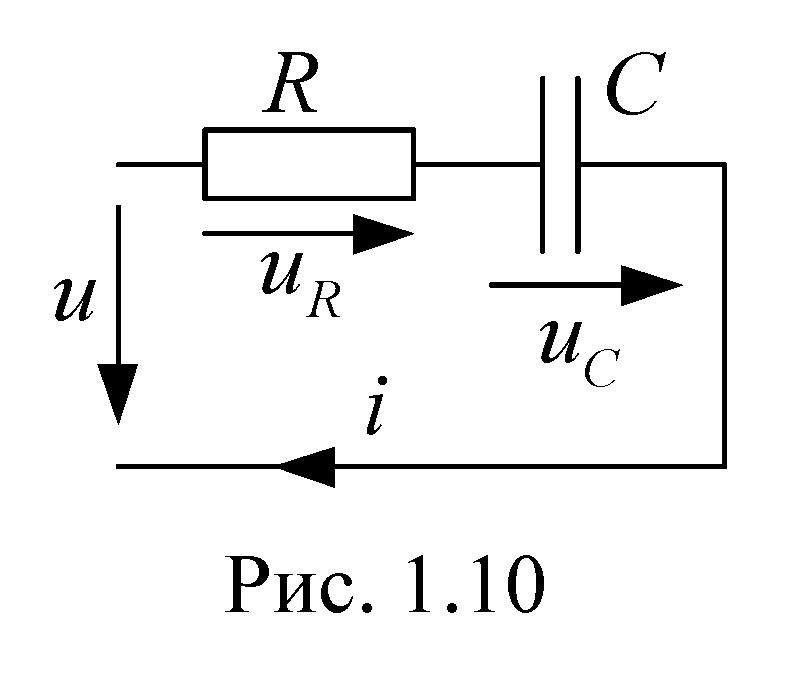

f1=500;  % Гц
f2=1000; % Гц
I1=1;   % А
I2=1.8; % А
U=100;  % В

Определить параметры цепи R и С

Z1=U/I1, Z2=U/I2

Z1 = 100

Z2 = 55.5556

syms Z1 Z2 R C omega1 omega2 
eq1=Z1^2==R^2+(1/(omega1*C))^2

$$eq1 = {Z_{1}}^{2}=R^{2}+\frac{1}{C^{2}\,{\omega_{1}}^{2}}$$

eq2=Z2^2==R^2+(1/(omega2*C))^2

$$eq2 = {Z_{2}}^{2}=R^{2}+\frac{1}{C^{2}\,{\omega_{2}}^{2}}$$

slv=solve([eq1,eq2],[R C])

slv = struct with fields:
    R: [4×1 sym]
    C: [4×1 sym]


R=slv.R(3)

$$R = \sqrt{\frac{\left(Z_{1}\,\omega_{1}+Z_{2}\,\omega_{2}\right)\,\left(Z_{1}\,\omega_{1}-Z_{2}\,\omega_{2}\right)}{\left(\omega_{1}+\omega_{2}\right)\,\left(\omega_{1}-\omega_{2}\right)}}$$

C=slv.C(3)

$$C = \frac{\sqrt{-\frac{\left(\omega_{1}+\omega_{2}\right)\,\left(\omega_{1}-\omega_{2}\right)}{\left(Z_{1}+Z_{2}\right)\,\left(Z_{1}-Z_{2}\right)}}}{\omega_{1}\,\omega_{2}}$$

digits(4)
R=vpa(subs(R,[Z1 Z2 omega1 omega2],[100 55.6 2*pi*500 2*pi*1000])) 

$$R = 28.08$$

% 28 Ом
C=vpa(subs(C,[Z1 Z2 omega1 omega2],[100 55.6 2*pi*500 2*pi*1000])) 

$$C = 3.317e-6$$

% 3.3 мкФ